Przykład 1. Złe przedstawienie wykresu.

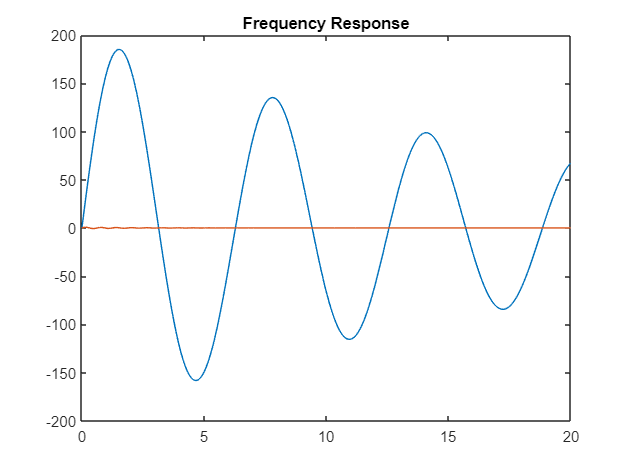

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
plot(x, y1)
hold on
plot(x, y2)
hold off
% Add title and x axis label
title('Frequency Response')

Przykład 2. Złe przedstawienie danych

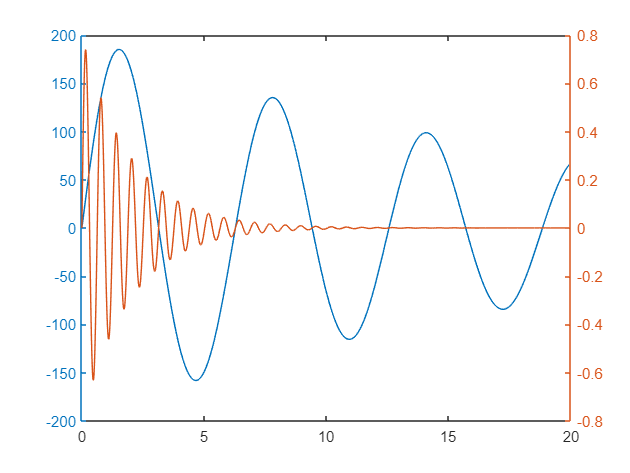

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
yyaxis left
plot(x, y1)
yyaxis right
plot(x, y2)

Przykład 3. Dobre przedstawienie danych.

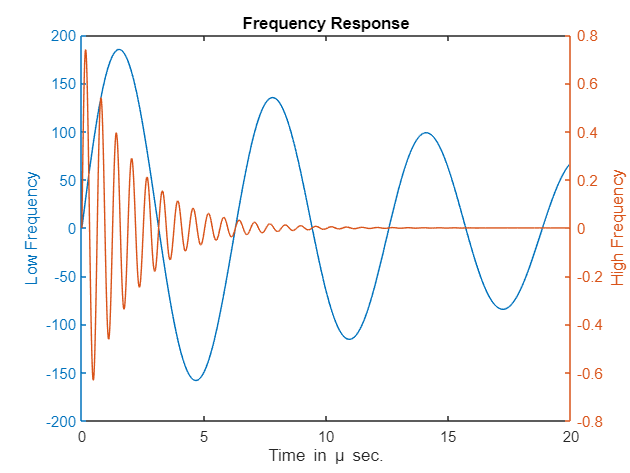

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
yyaxis left
plot(x, y1)
ylabel('Low Frequency')
yyaxis right
plot(x, y2)
ylabel('High Frequency')
% Add title and x axis label
xlabel('Time in \mu sec.')
title('Frequency Response')

Zadanie 0a. 

Przedstaw na jednym wykresie funkcję: $x^2 -y^2 =c$ w zależności od parametru $c\in \left\lbrace -4,-2,0,2,4\right\rbrace$. Przedstaw wyniki na jednym wykresie.

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

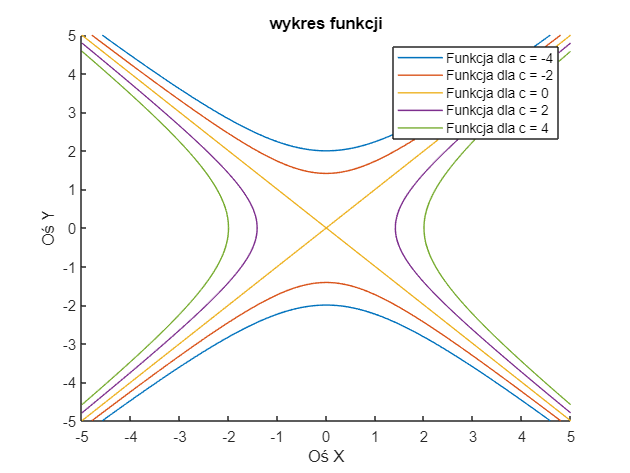

close all
c = [-4,-2,0,2,4];
figure
hold on
title('wykres funkcji')
for i = 1:size(c,2)
    fimplicit(@(x, y) x.^2 - y.^2 - c(i))
end
hold off
xlabel("Oś X")

ylabel("Oś Y")
legend('Funkcja dla c = -4', 'Funkcja dla c = -2', "Funkcja dla c = 0", "Funkcja dla c = 2", "Funkcja dla c = 4")
xticks(-5:1:5)

Zadanie 0b.

Dane są funkcję: $f\left(x\right)=x^2$ oraz $g\left(x\right)=5+\sin \left(x\right)$

Rozwiąż graficznie równanie: $f\left(x\right)=g\left(x\right)$

Przedstaw w dwóch postaciach:

- użyj legendy do opisu wykresu,

- użyj funkcji text by narzucić tekst na wykres

Nadaj tytuł, podpisz osie (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

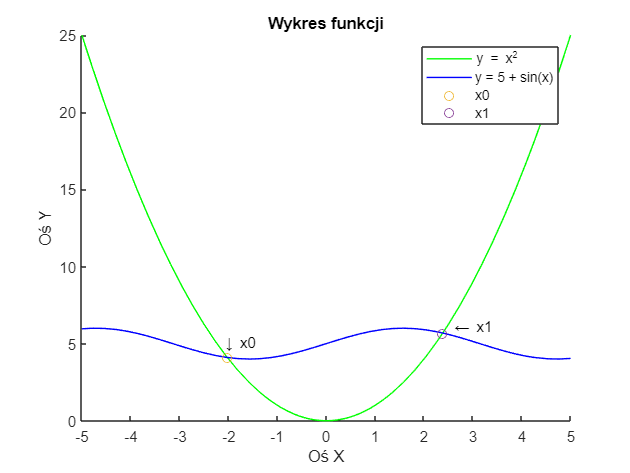

close all
syms x y
f = x.^2;
g = 5 + sin(x);
m0 = [ vpasolve(f == g, x,[-3 -1]) vpasolve(f == g, x,[2 3]) ];
figure
hold on
title("Wykres funkcji")
xlabel("Oś X")
ylabel("Oś Y")
fplot(@(x) x.^2, "g")
fplot(@(x) 5 + sin(x), "b")
text(-2.1,5,'\downarrow x0')
text(2.6,6,'\leftarrow x1')
for i=1:size(m0, 2)
    plot(m0(i), m0(i).^2, "o")
end
hold off
legend("y = x^2", "y = 5 + sin(x)", "x0", "x1")
xticks(-5:1:5)

Wczytywanie pliku:

- load

- xlsread

- readmatrix

- readtable

- readcell

Zadanie 1. 

Wczytaj plik ***temperatury.xlsx ***

Przedstaw dane na wykresie (wykresach) oraz jednym oknie. 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

Odpowiedz na pytania:

- Jaka była średnia temperatura maksymalna oraz minimalna dla danego roku?

- Który miesiąc był najzimniejszy a który najgorętszy?

- Ile wynosi różnica pomiędzy skrajnymi temperaturami średnimi?

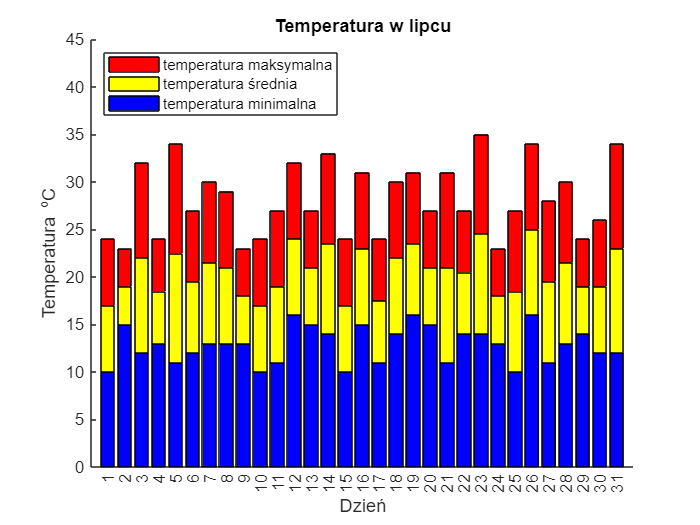

close all
clear 
t = xlsread('temperatury.xlsx');
dzien = t(:,1);
min_tem = t(:,2);
max_tem = t(:,3);
srednia = t(:,4);
figure
hold on
bar(dzien,max_tem,'r')
bar(dzien,srednia,'y')
bar(dzien,min_tem,'b')
hold off
xticks(1:1:31)
yticks(0:5:45)
axis([0,32,0,45])
legend('temperatura maksymalna','temperatura średnia','temperatura minimalna','Location','northwest')
title('Temperatura w lipcu')
xlabel('Dzień')
ylabel('Temperatura ^oC')


%1. średnia maxymalna to 25 stopnie a minimalna to 17 stopni
disp('Jaka była średnia temperatura maksymalna oraz minimalna dla danego roku?')

Jaka była średnia temperatura maksymalna oraz minimalna dla danego roku?


srednia_max = max(srednia)

srednia_max = 25

srednia_min = min(srednia)

srednia_min = 17

%2. Nie jeteśmy wstanie odczytać z wykresu jaki miesiąc jest najcieplejszy a jaki najzimnijeszy. Najcieplejszy dzień to 23-dzień natomiast najzimniejszy to 1, 10, 15 oraz 25-dzień miesiąca
disp('Który dzień był najzimniejszy a który najgorętszy?')

Który dzień był najzimniejszy a który najgorętszy?



najciplejszy = find(max_tem == max(max_tem))

najciplejszy = 23

najzimniejszy  = find(min_tem == min(min_tem))

najzimniejszy =      1
    10
    15
    25




%3. wynosi 8 stopni
disp('Ile wynosi różnica pomiędzy skrajnymi temperaturami średnimi?')

Ile wynosi różnica pomiędzy skrajnymi temperaturami średnimi?


roznica = srednia_max - srednia_min

roznica = 8

%Wnioski: wykres bar jest odpowiednim wykresem do przedstawienia temperatury ponieważ pozwala na porównanie różnych wartości np.: takich jak temeperatura w poszczególnych dniach)

Zadanie 2. 

Wczytaj plik ***pogoda.xlsx***

Przedstaw dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

Odpowiedz na pytania:

- Jaka jest średnia warość opadów oraz średnia temperatura?

- Czy wysokość temperatury wpływa na ilość opadów? Czy istnieje korelacja?

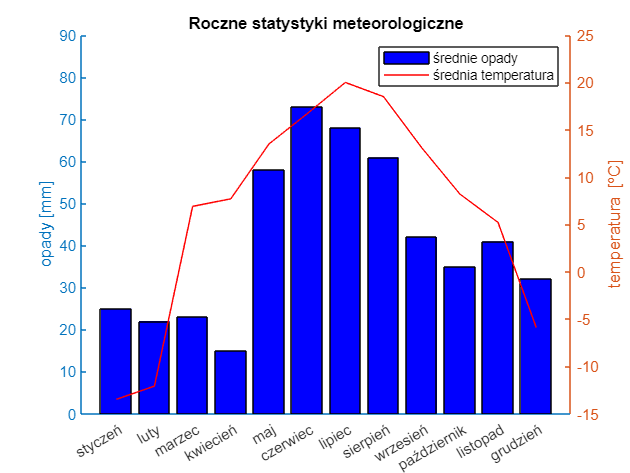

close all
clear 
p = xlsread('pogoda.xlsx');
sr_tem = p(:,1);
sr_op = p(:,2);
mies=categorical(["styczeń", "luty", "marzec", "kwiecień", "maj", "czerwiec", "lipiec", "sierpień", "wrzesień", "październik", "listopad", "grudzień"]);
mies=reordercats(mies,["styczeń", "luty", "marzec", "kwiecień", "maj", "czerwiec", "lipiec", "sierpień", "wrzesień", "październik", "listopad", "grudzień"]);
figure
hold on
yyaxis left
bar(mies,sr_op,'b')
ylabel('opady [mm]')
ylim([0,90])

yyaxis right
plot(1:12, sr_tem,'r')
ylabel('temperatura [^oC]')
ylim([-15,25])

hold off
title('Roczne statystyki meteorologiczne')
legend('średnie opady', 'średnia temperatura')


%1.
disp('Jaka jest średnia warość opadów oraz średnia temperatura?')

Jaka jest średnia warość opadów oraz średnia temperatura?


srednia_wartosc_opadow = mean(sr_op)

srednia_wartosc_opadow = 41.2500

srednia_wartosc_temperatury = mean(sr_tem)

srednia_wartosc_temperatury = 6.5250


%2. Z wykresu można odczytać że im cieplej tym większe opady
%Wnioski: Przedstawienie obu wykresów z osobną osią Y dla średniej temperatury oraz osobną dla opadów sprawia  że wykres jest czytelniejszy.




Zadanie 3. 

Załaduj wbudowane dane ***gas.mat***

Przedstaw dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

Odpowiedz na pytania:

- Jaka jest średnia wartość ceny?

- Ile wynosi odchylenie standardowe?

- Jaka jest średnia różnica pomiędzy danymi cenami?

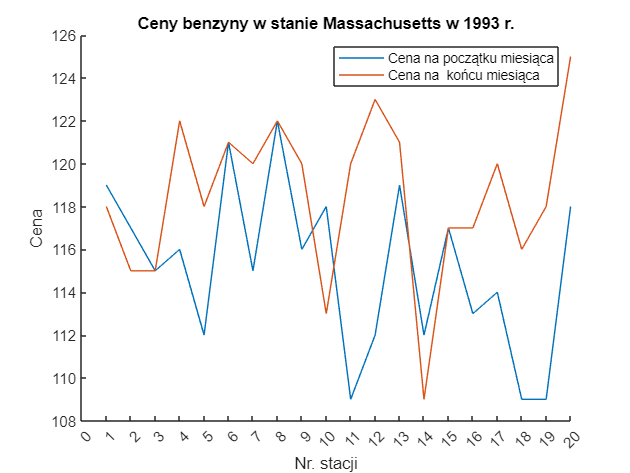

close all
clear 
load gas.mat
figure
hold on
plot(price1)
plot(price2)
title("Ceny benzyny w stanie Massachusetts w 1993 r.")
xlabel("Nr. stacji")
ylabel("Cena")
legend("Cena na początku miesiąca","Cena na  końcu miesiąca")
xticks(0:1:20)

%1.
disp('Jaka jest średnia wartość ceny?')

Jaka jest średnia wartość ceny?


srednia_cena_na_poczatku_miesiaca = mean(price1)

srednia_cena_na_poczatku_miesiaca = 115.1500

srednia_cena_na_koncu_miesiaca = mean(price2)

srednia_cena_na_koncu_miesiaca = 118.5000

%2.
disp('Ile wynosi odchylenie standardowe?')

Ile wynosi odchylenie standardowe?


odchylenie_standardowe_na_poczatku_miesiaca = std(price1)

odchylenie_standardowe_na_poczatku_miesiaca = 3.8699

odchylenie_standardowe_na_koncu_miesiaca = std(price2)

odchylenie_standardowe_na_koncu_miesiaca = 3.7346

%3.
disp('Jaka jest średnia różnica pomiędzy danymi cenami?')

Jaka jest średnia różnica pomiędzy danymi cenami?


srednia_roznica = sum(abs(price1-price2))/size(price1,1)

srednia_roznica = 4.4500

% Wnioski: dzięki użyciu dwóch wykresów liniowych jesteśmy wstanie porównać ceny paliwa na końcu oraz na początku miesiąca na poszczególnych stacjach oraz porównywać ceny paliw poszczególnych stacji





Zadanie 4. 

Załaduj wbudowane dane ***cereal.mat***

Przedstaw wybrane dane na wykresie (wykresach). Nadaj tytuł, podpisz osie, dodaj legendę.

Odpowiedz na pytania:

- Jaka jest największa kaloryczność produktów?

- Więdząc, że osoby ćwiczące potrzebują dużą ilość białka, które produkty zostaną polecone?

- Które z produktów zawierają małą sumaryczną ilość węgli, tłuszczów oraz cukrów?

close all
clear 
load cereal.mat
nazwy = Name(7:12, 1);
kalorie = Calories(7:12, 1);
tluszcz = Fat(7:12, 1);
cukier = Sugars(7:12, 1);
figure
disp('Wykresy przedstawiają wartości odżywcze płatków śniadaniowych')

Wykresy przedstawiają wartości odżywcze płatków śniadaniowych


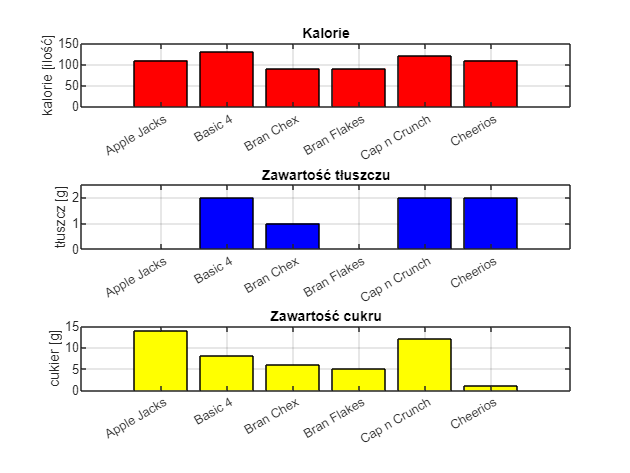

subplot(3,1,1)
bar(kalorie,'r')
xticklabels(nazwy)
title('Kalorie')
ylabel('kalorie [ilość]')
ylim([0,150])
grid
subplot(3,1,2)
bar(tluszcz,'b')
xticklabels(nazwy)
title('Zawartość tłuszczu')
ylabel('tłuszcz [g]')
ylim([0,2.5])
grid
subplot(3,1,3)
bar(cukier,'y')
title('Zawartość cukru')
xticklabels(nazwy)
ylabel('cukier [g]')
ylim([0,15])
grid





% Wykresy zostały sworzone dla wybranych wartości odżywczych oraz wybranych produktów natomiast odpowiedzi odnoszą się do całej bazy
%1.
disp('Jaka jest największa kaloryczność produktów?')

Jaka jest największa kaloryczność produktów?


najw_kal = max(Calories)

najw_kal = 160

%2. 
disp('Więdząc, że osoby ćwiczące potrzebują dużą ilość białka, które produkty zostaną polecone?')

Więdząc, że osoby ćwiczące potrzebują dużą ilość białka, które produkty zostaną polecone?


[najw,idx] = max(Protein);
najw_bialka = Name(idx)

najw_bialka = 1×1 cell array
    {'Cheerios'}


%3. 
disp('Które z produktów zawierają małą sumaryczną ilość węgli, tłuszczów oraz cukrów?')

Które z produktów zawierają małą sumaryczną ilość węgli, tłuszczów oraz cukrów?


[najm,idx1] = min(Carbo + Fat + Sugars);
najm_wartosc_sumaryczna = Name(idx1)

najm_wartosc_sumaryczna = 1×1 cell array
    {'Quaker Oatmeal'}


% Wnioski: takie usytuowanie wykresów pozwala łatwo porównywać wartości odżywcze dla poszczególnych płatków oraz poprawia czytelność wykresów










Zadanie 5. 

Załaduj wbudowane dane ***cities.mat***

Przedstaw wybrane dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

Odpowiedz na pytania:

- Które z miast ma najlepszy ranking w kategorii ekonomii?

- Które z miast jest najbardziej, a które najmniej niebezpieczne?

- Które z miast na podstawie otrzymanych danych wybrałbyś do zamieszkania i dlaczego?

close all
clear 
load cities.mat
figure 
nazwy = names(1:4,1:size(names, 2));
ocena = ratings(1:4,:);
kategorie = categories(1:9,1:14);
disp('Oceny jakości życia dla wybranych amerykańskich obszarów metropolitalnych')

Oceny jakości życia dla wybranych amerykańskich obszarów metropolitalnych


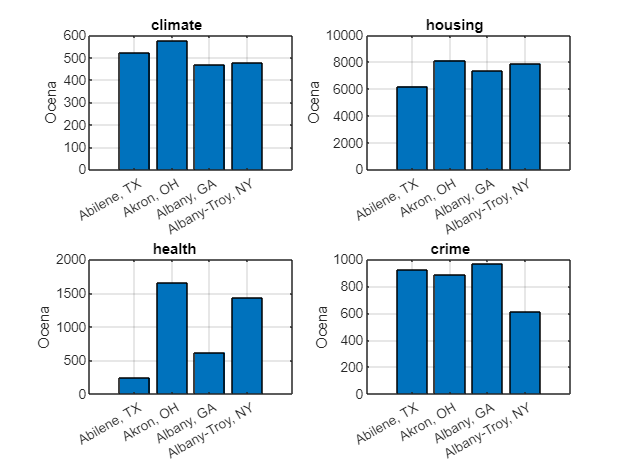

subplot(2,2,1)
bar(ocena(:,1))
xticklabels(nazwy)
title(kategorie(1,:))
yticks(0:100:600)
ylabel('Ocena')
grid

subplot(2,2,2)
bar(ocena(:,2))
xticklabels(nazwy)
title(kategorie(2,:))
yticks(0:2000:10000)
ylabel('Ocena')
grid

subplot(2,2,3)
bar(ocena(:,3))
xticklabels(nazwy)
title(kategorie(3,:))
ylabel('Ocena')
grid


subplot(2,2,4)
bar(ocena(:,4))
xticklabels(nazwy)
title(kategorie(4,:))
yticks(0:200:1000)
ylabel('Ocena')
grid

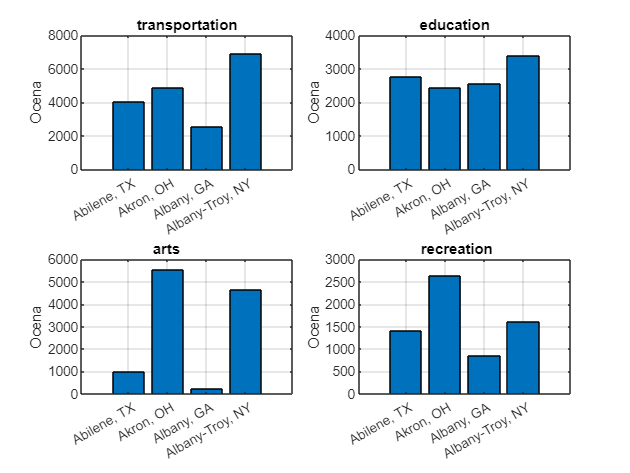


figure

subplot(2,2,1)
bar(ocena(:,5))
xticklabels(nazwy)
title(kategorie(5,:))
ylabel('Ocena')
grid


subplot(2,2,2)
bar(ocena(:,6))
xticklabels(nazwy)
title(kategorie(6,:))
ylabel('Ocena')
grid

subplot(2,2,3)
bar(ocena(:,7))
xticklabels(nazwy)
title(kategorie(7,:))
yticks(0:1000:6000)
ylabel('Ocena')
grid

subplot(2,2,4)
bar(ocena(:,8))
xticklabels(nazwy)
title(kategorie(8,:))
yticks(0:500:3000)
ylabel('Ocena')
grid

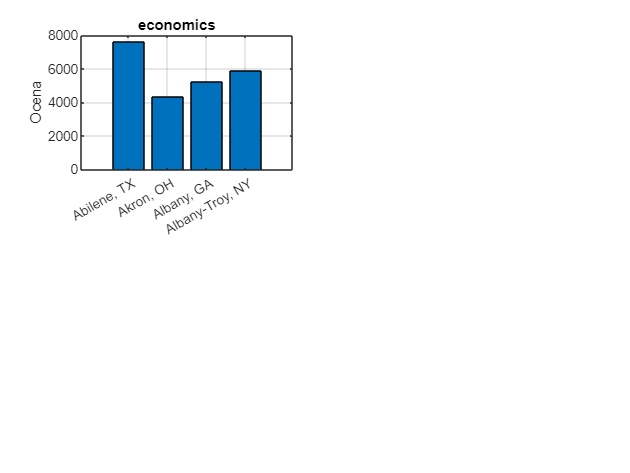


figure
subplot(2,2,1)
bar(ocena(:,9))
xticklabels(nazwy)
title(kategorie(9,:))
ylabel('Ocena')
grid


% Wykresy zostały sworzone dla wybranych obszarów natomiast odpowiedzi odnoszą się do całej bazy danych

%1
disp('Które z miast ma najlepszy ranking w kategorii ekonomii?')

Które z miast ma najlepszy ranking w kategorii ekonomii?


idx  = find(ratings(:,9) == max(ratings(:,9)));
najlepsza_ekonomia = names(idx,1:size(names, 2))

najlepsza_ekonomia = 'Midland, TX                                '

%2
disp('Które z miast jest najbardziej, a które najmniej niebezpieczne?')

Które z miast jest najbardziej, a które najmniej niebezpieczne?


idx1  = find(ratings(:,4) == max(ratings(:,4)));
idx2  = find(ratings(:,4) == min(ratings(:,4)));
najbardziej = names(idx1,1:size(names, 2))

najbardziej = 'New York, NY                               '

najmniej = names(idx2,1:size(names, 2))

najmniej = 'Wheeling, WV-OH                            '

%3 Które z miast na podstawie otrzymanych danych wybrałbyś do zamieszkania i dlaczego?
% Z wybranych obszarów przedstawionych na wykresie wybrałbym Albany_Troy, NY ponieważ w każdej kategorii ma stosunkowo wysoką ocene, a także gdyż w przypadku przestępczości ocena jest niska

% Wnioski: takie usytuowanie wykresów pozwala łatwo porównywać wartości dla poszczególnych obszarów oraz poprawia czytelność wykresów gdyż nie zawiera zbyt dużej ilości danych na jednym wykresie




Zadanie 6. 

Załaduj wbudowane dane*** FisherIris.mat***

Podziel dane *meas* według gatunku 

((1,50)->setosa, 

(51,100)-> virginica, 

(101,151)-> versicolor)

Policz średnią i odchylenie dla każdej kolumny, utwórz errorbar. 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

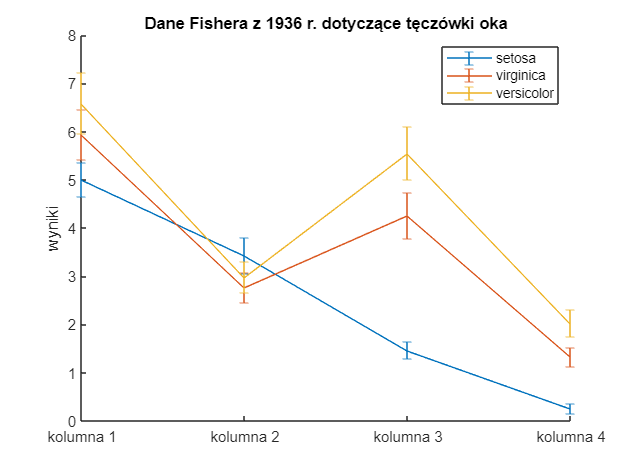

close all
clear 
load FisherIris.mat
setosa = meas(1:50, :);
virginica = meas(51:100, :);
versicolor = meas(101:150, :);
for i = 1:4
    srednia_setosa(i) = mean(setosa(:,i));
    odchylenie_setosa(i) = std(setosa(:,i));
    srednia_virginica(i) = mean(virginica(:,i));
    odchylenie_virginica(i) = std(virginica(:,i));
    srednia_versicolor(i) = mean(versicolor(:,i));
    odchylenie_versicolor(i) = std(versicolor(:,i));
end

x = ["kolumna 1" "kolumna 2" "kolumna 3" "kolumna 4" ];

hold on
errorbar([1 2 3 4],srednia_setosa,odchylenie_setosa)
errorbar([1 2 3 4],srednia_virginica,odchylenie_virginica)
errorbar([1 2 3 4],srednia_versicolor,odchylenie_versicolor)
hold off
xticks(1:1:5)
xticklabels(x)
legend('setosa', 'virginica', 'versicolor')
title('Dane Fishera z 1936 r. dotyczące tęczówki oka')
ylabel('wyniki')


% Wnioski: Wykres errorbar pozwala na zaznaczenie np: błędu pomiaru w zdeklarowanym przez nas miejscu



Zadanie 7*. 

Załaduj wbudowane dane ***spine X***

Przedstaw dane X na wykresach różnych wykresach (plot, hist,mesh). Spróbuj na podstawie wykresów zgadnąć co to za dane.

Na końcu użyj funkcji imagesc(X).

Dopisz wnioski i spostrzeżenia.

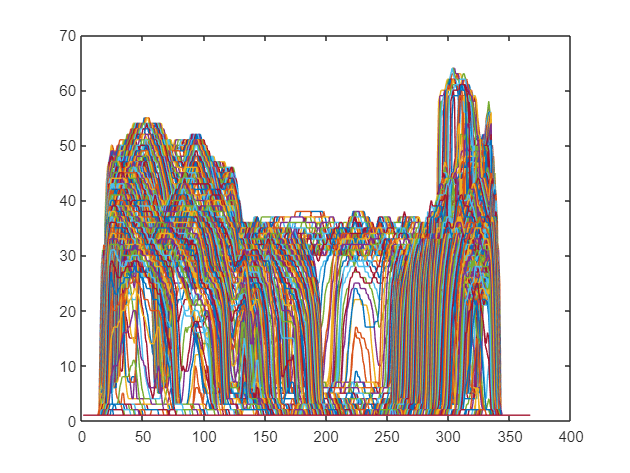

close all
clear 
load spine X
figure
plot(X) %wykres liniowy prezentujący płaszcyznę XZ (z lewej strony)

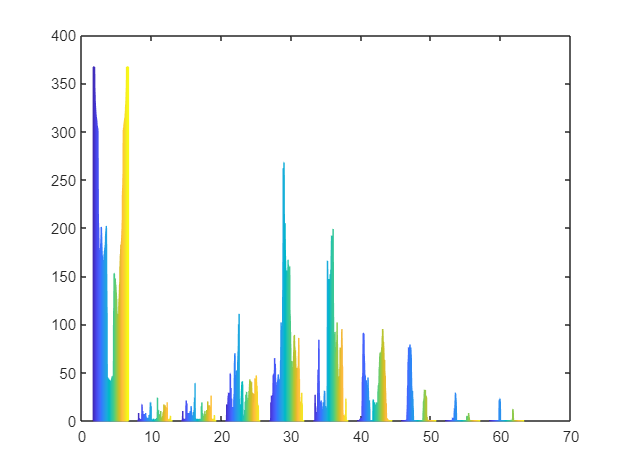

figure
hist(X) % wykres histogramu elementów

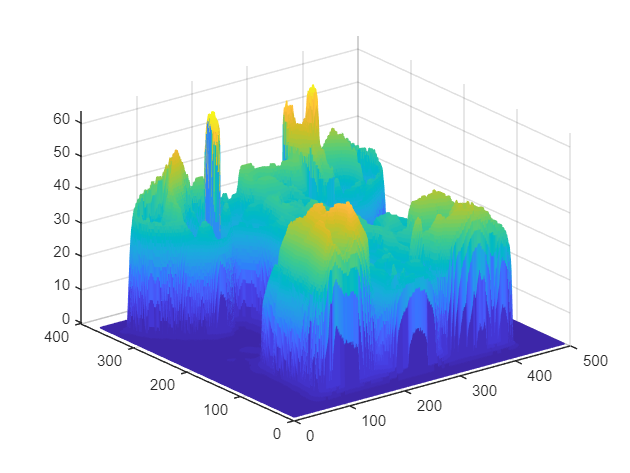

figure
mesh(X) % wykres w trójwymiarze 

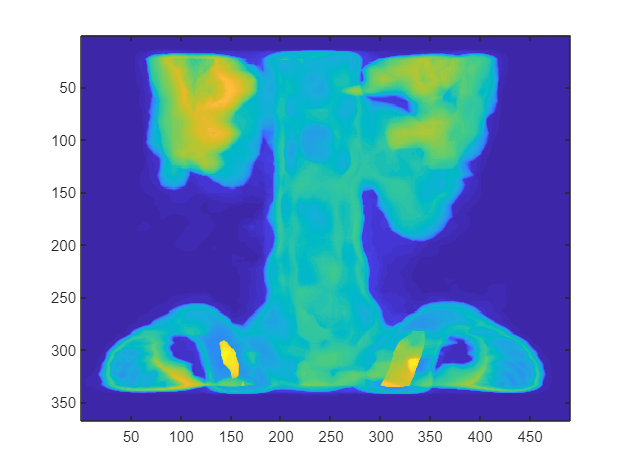

imagesc(X) % wykres przedstawiajacy płaszczyzne XY z góry


% Wnioski: jeden rodzaj danych można przedstawić w przeróżny sposób w zależności co chcemy pokazać